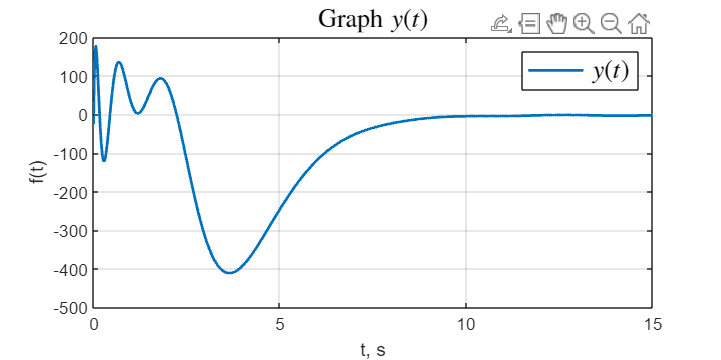

clear;

%=======Задающий сигнал======
G_g = [0 2 0;
    -2 0 0;
    0 0 0];
Y_g = [1 0 -2];
w_g0 = [1; 0; 1];

%======Система==========

A = [5 8 5; -6 -9 -8; 6 6 5];
B = [2; 0; 0];
C = [2 -3 -2];
Bf = [-3 1; 3 0; 0 0];
D = [7];
Df = [5 6];
x0 = [0; 0; 0];
%=====Внешнее возмущение====
G_f = [0 1 0 1;
    -26 -7 20 -11;
    0 1 -1 2;
    16 4 -14 8];
Y_f = [2 0 -2 1;
    -4 -2 4 -3];
w_f0 = [1; 1; 1; 1];
wfx_0 = [1; 1; 1; 1; 0; 0; 0];

%====Синтез К========
K = [-6.5 -0.25 0.25];

%====Синтез Кg========
Kg = [0.0468 0.2563 -0.3738];

%====Синтез Кf========
Kf = [16.0012 6.4817 -11.3156 6.2353];


%====Check obs ======
V = [Y_g; Y_g * G_g; Y_g * G_g^2];
r = rank(V);

%====Gamma & Y========
G = [-1 0 0; 0 -2 0; 0 0 -1.5];
Y = [1; 1; 1];
U = [Y G*Y G^2*Y];
ru = rank(U);

%=====Q-searching=======
%{
cvx_begin sdp

variable Q(3, 3)

Q*G_g-G*Q==Y*Y_g;
cvx_end

disp(Q);
disp(det(Q));
%}

Q = [0.2000 -0.4000 -2.0000;
    0.2500 -0.2500 -1.0000;
    0.2400 -0.3200 -1.3333];
iQ = pinv(Q);

%=====L-searching====
z = [0 0 0; 0 0 0; 0 0 0; 0 0 0];
A_b = [G_f z;
    Bf*Y_f A];
C_b = [Df*Y_f C];
B_b = [0; 0; 0; 0; B];

V_L = [C_b; C_b*A_b; C_b*A_b^2;
    C_b*A_b^3; C_b*A_b^4; C_b*A_b^5;
    C_b*A_b^6];
rvl = rank(V_L);

%e_A = eig(A_b)

G_L = [-1 0 0 0 0 0 0;
        0 -1.5 0 0 0 0 0;
        0 0 -2 0 0 0 0;
        0 0 0 -2.5 0 0 0;
        0 0 0 0 -3.5 0 0;
        0 0 0 0 0 -4 0;
        0 0 0 0 0 0 -4.5];
Y_L = [1; 1; 1; 1; 1; 1; 1];

U_L = [Y_L G_L*Y_L G_L^2*Y_L G_L^3*Y_L G_L^4*Y_L G_L^5*Y_L G_L^6*Y_L];

rul = rank(U_L);
%{
cvx_begin sdp

variable Q_L(7, 7)

G_L*Q_L-Q_L*A_b == Y_L*C_b;
cvx_end
d = det(Q_L)
L = pinv(Q_L)*Y_L
%}

L = [-0.0062; 0.3177; 1.9709; 3.1379; -6.5057; -10.4921;
   10.7697];


%====Sim=====

open_system('task_2_sim');
set_param('task_2_sim/g', 'VariableName', 'g')
set_param('task_2_sim/x_', 'VariableName', 'x_')
set_param('task_2_sim/x', 'VariableName', 'x')
set_param('task_2_sim/y', 'VariableName', 'y')
set_param('task_2_sim/u', 'VariableName', 'u')
set_param('task_2_sim/e', 'VariableName', 'e')
set_param('task_2_sim/eg', 'VariableName', 'eg')
set_param('task_2_sim/ef', 'VariableName', 'ef')


out = sim('task_2_sim');
figure('Position', [100 100 800 400])

plot(out.y,'-', 'LineWidth',1.5);

grid()
title('Graph $y(t)$','Interpreter','latex',  'FontSize', 14)
legend('$y(t)$', 'Interpreter','latex',  'FontSize', 14)
ylabel('f(t)')
xlabel('t, s')

%hold off

